% load dataset
trainDir = 'E:\Two angle\train'; % training set
valDir = 'E:\Two angle\test'; % test set

load('all_trained_models_2_view.mat')
trainedOriginalNet=all_trained_Nets{4, 2};
% create Datastore    
imdsTrain = imageDatastore(trainDir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');
imdsTest = imageDatastore(valDir, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% obtain image size 
inputSize = trainedOriginalNet.Layers(1).InputSize;

% augment image 
augimdsTrain = augmentedImageDatastore(inputSize, imdsTrain);
augimdsTest  = augmentedImageDatastore(inputSize, imdsTest);
TTest = imdsTest.Labels;
classNames = categories(imdsTrain.Labels);
classes = categories(TTest);
YTest = minibatchpredict(trainedOriginalNet,augimdsTest); 
YTest = onehotdecode(YTest,classNames,2);
accuracyOfTrainedNet = mean(YTest == TTest)*100; 
layerG = layerGraph(trainedOriginalNet); 
layerG = removeLayers(layerG,layerG.OutputNames); % 移除输出层以便进行剪枝
net = dlnetwork(layerG); 
analyzeNetwork(net) 

maxPruningIterations = 10; % max pruning iterations
maxToPrune = 385; % prune filter number
% parameter setting
learnRate = 1e-2;
momentum = 0.9;
miniBatchSize = 125;
numMinibatchUpdates  = 50;
validationFrequency = 1;
% create prunable net
prunableNet = taylorPrunableNetwork(net);
maxPrunableFilters = prunableNet.NumPrunables;


% fprintf('Total number of prunable filters in the network: %d\n', maxPrunableFilters);


% Create mini batch data queues for training and testing
mbqTrain = minibatchqueue(augimdsTrain, ...
    MiniBatchSize = miniBatchSize, ...
    MiniBatchFcn = @preprocessMiniBatchTraining, ...
    OutputAsDlarray = [1 1], ...
    OutputEnvironment = ["auto","auto"], ...
    PartialMiniBatch = "return", ...
    MiniBatchFormat = ["SSCB",""]);
mbqTest = minibatchqueue(augimdsTest,...
    MiniBatchSize = miniBatchSize,...
    MiniBatchFcn = @preprocessMiniBatchTraining, ...
    OutputAsDlarray = [1 1], ...
    OutputEnvironment = ["auto","auto"], ...
    PartialMiniBatch = "return", ...
    MiniBatchFormat = ["SSCB",""]);

% Plot loss, accuracy, and number of filters
figure("Position",[10,10,700,700])
tl = tiledlayout(3,1); 
lossAx = nexttile;
lineLossFinetune = animatedline(Color=[0.85 0.325 0.098]);
ylim([0 inf])
xlabel("Fine-Tuning Iteration")
ylabel("Loss")
grid on
title("Mini-Batch Loss During Pruning")
xTickPos = [];

accuracyAx = nexttile;
lineAccuracyPruning = animatedline(Color=[0.098 0.325 0.85],LineWidth=2,Marker="o");
ylim([50 100])
xlabel("Pruning Iteration")
ylabel("Accuracy")
grid on
addpoints(lineAccuracyPruning,0,accuracyOfTrainedNet)
title("Validation Accuracy After Pruning")

numPrunablesAx = nexttile;
lineNumPrunables = animatedline(Color=[0.4660 0.6740 0.1880],LineWidth=2,Marker="^");
ylim([200 4000])
xlabel("Pruning Iteration")
ylabel("Prunable Filters")
grid on
addpoints(lineNumPrunables,0,double(maxPrunableFilters))
title("Number of Prunable Convolution Filters After Pruning")

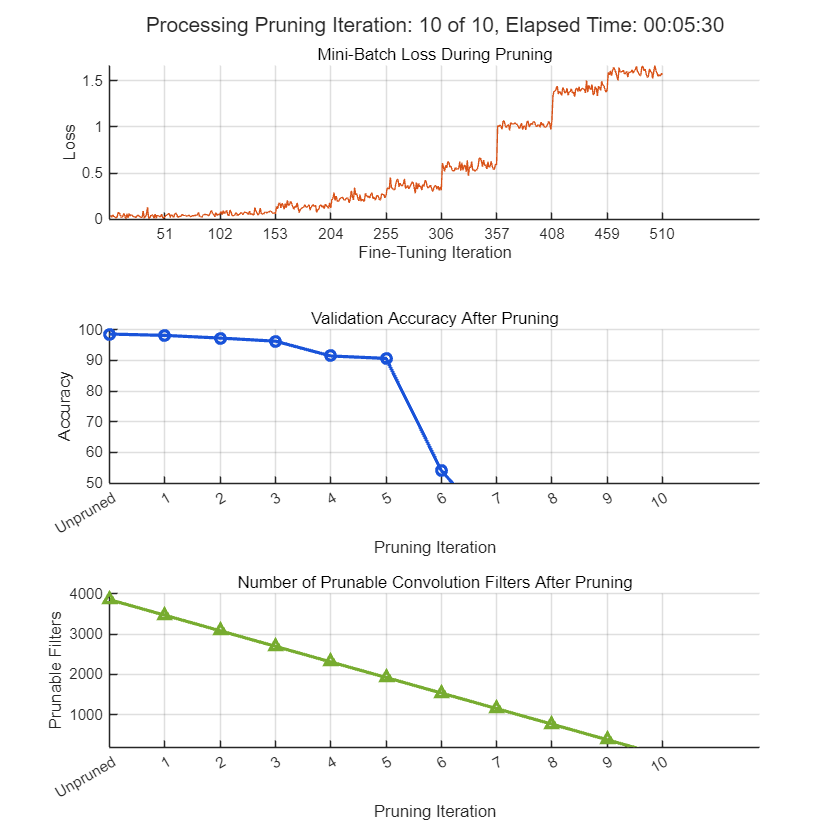

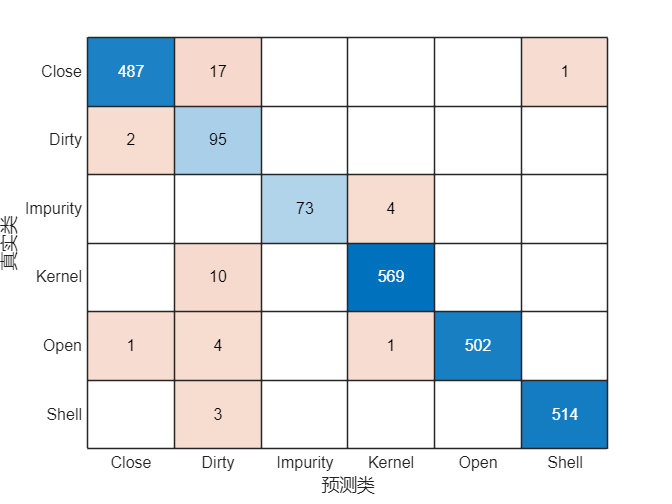

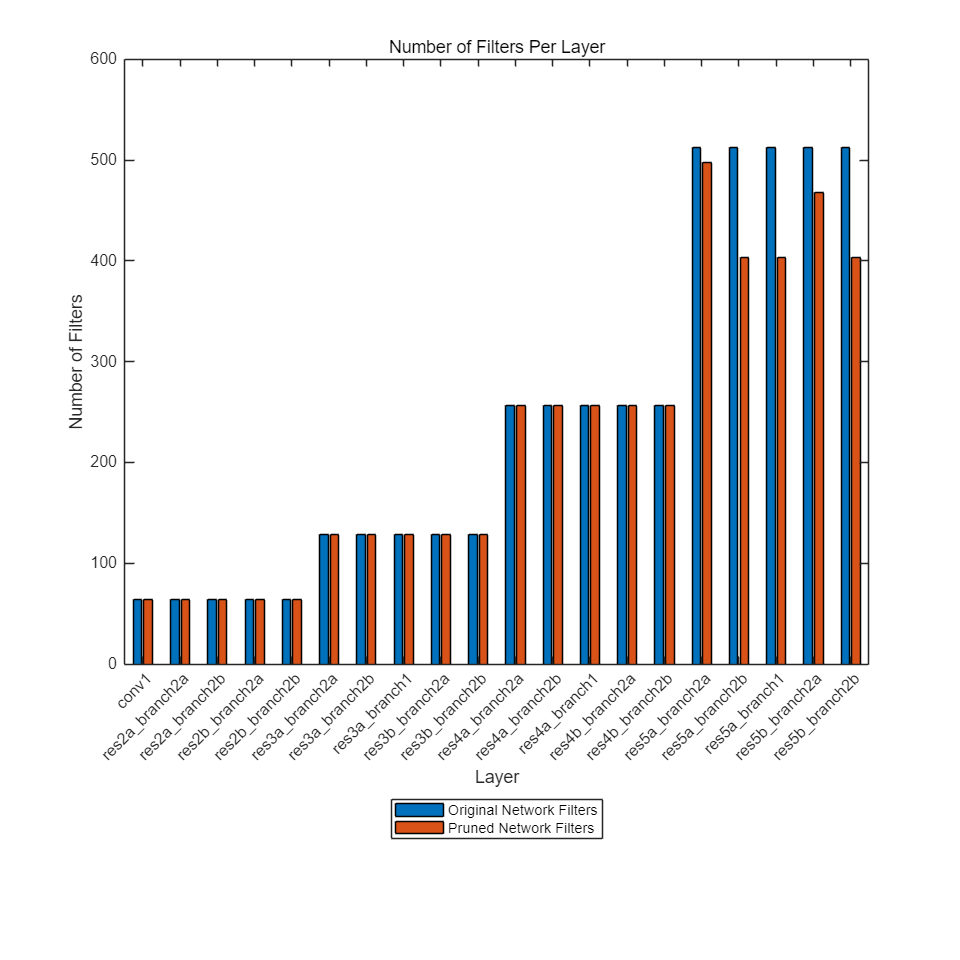

Pruning Iteration 1: Accuracy = 98.12%, Number of Prunable Filters = 3465


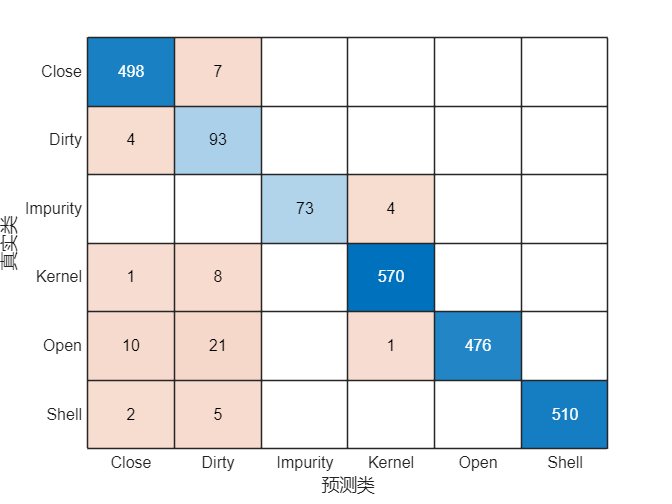

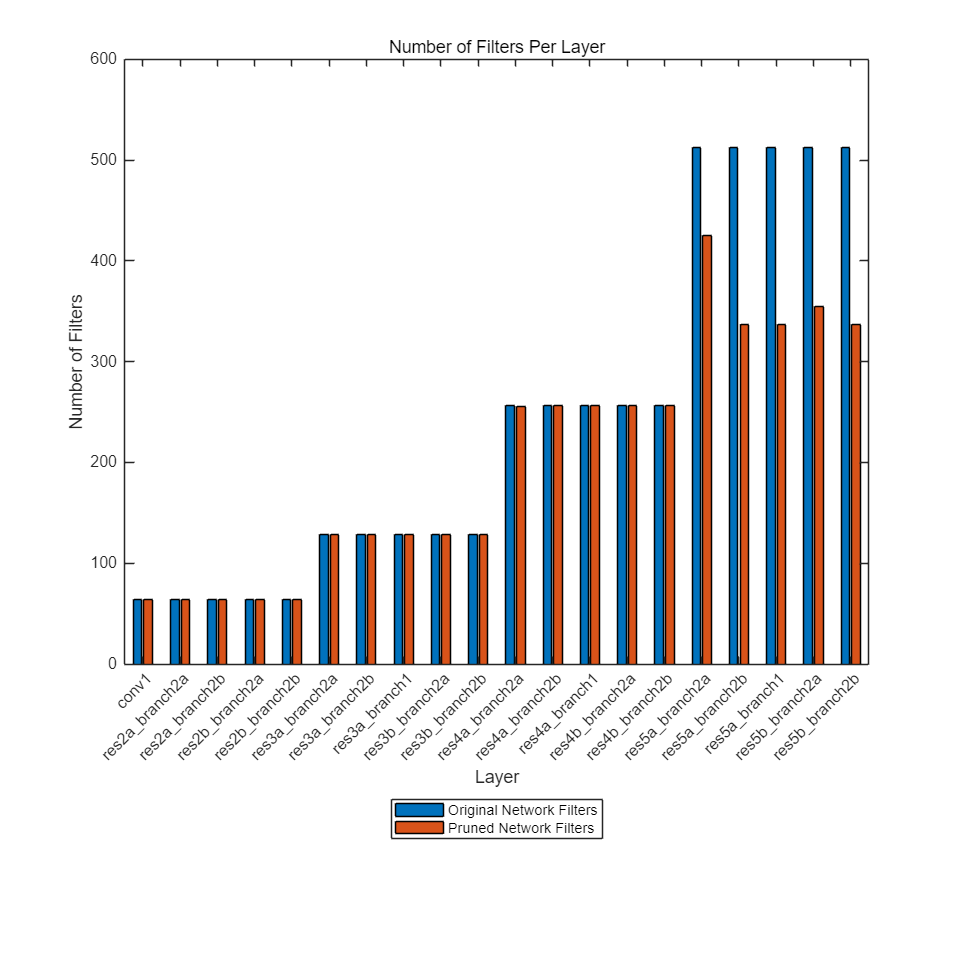

Pruning Iteration 2: Accuracy = 97.24%, Number of Prunable Filters = 3080


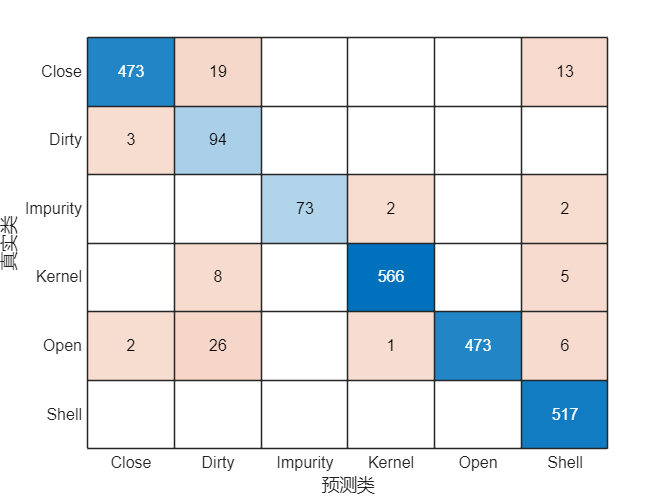

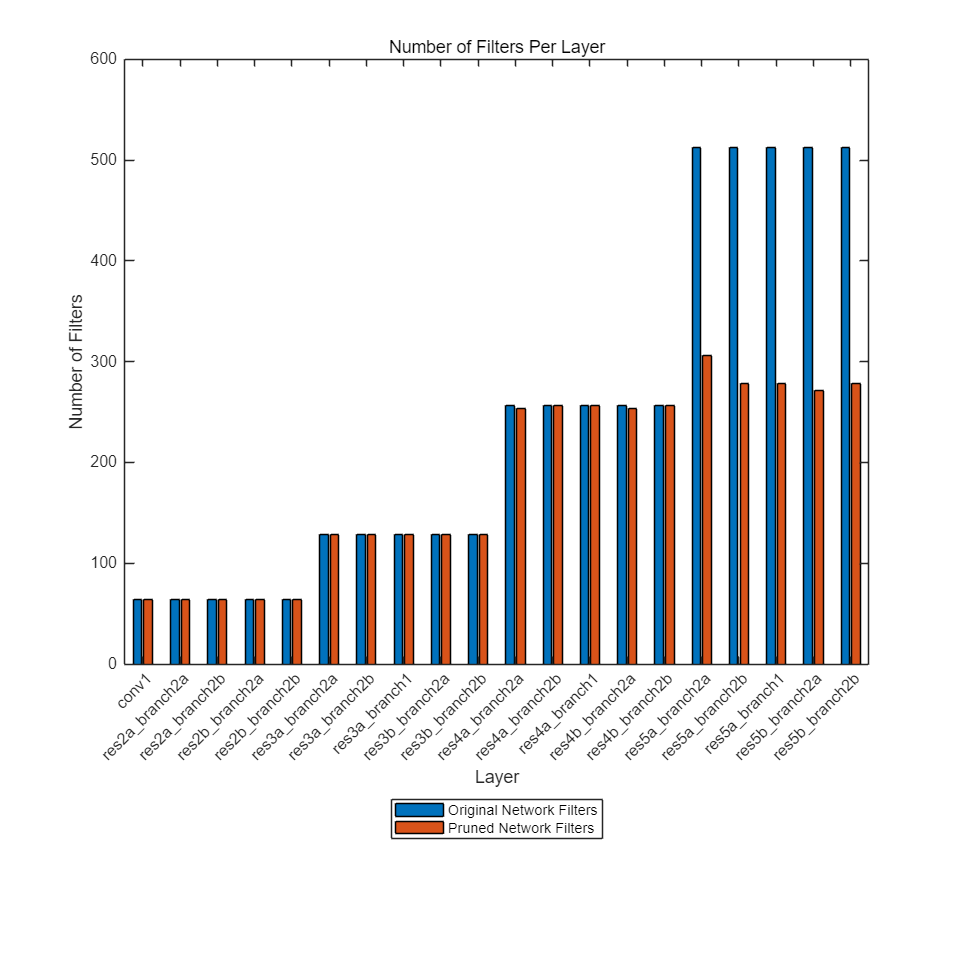

Pruning Iteration 3: Accuracy = 96.23%, Number of Prunable Filters = 2695


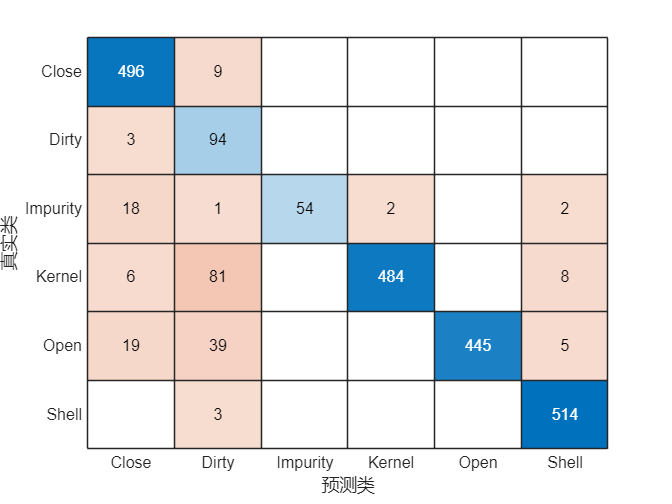

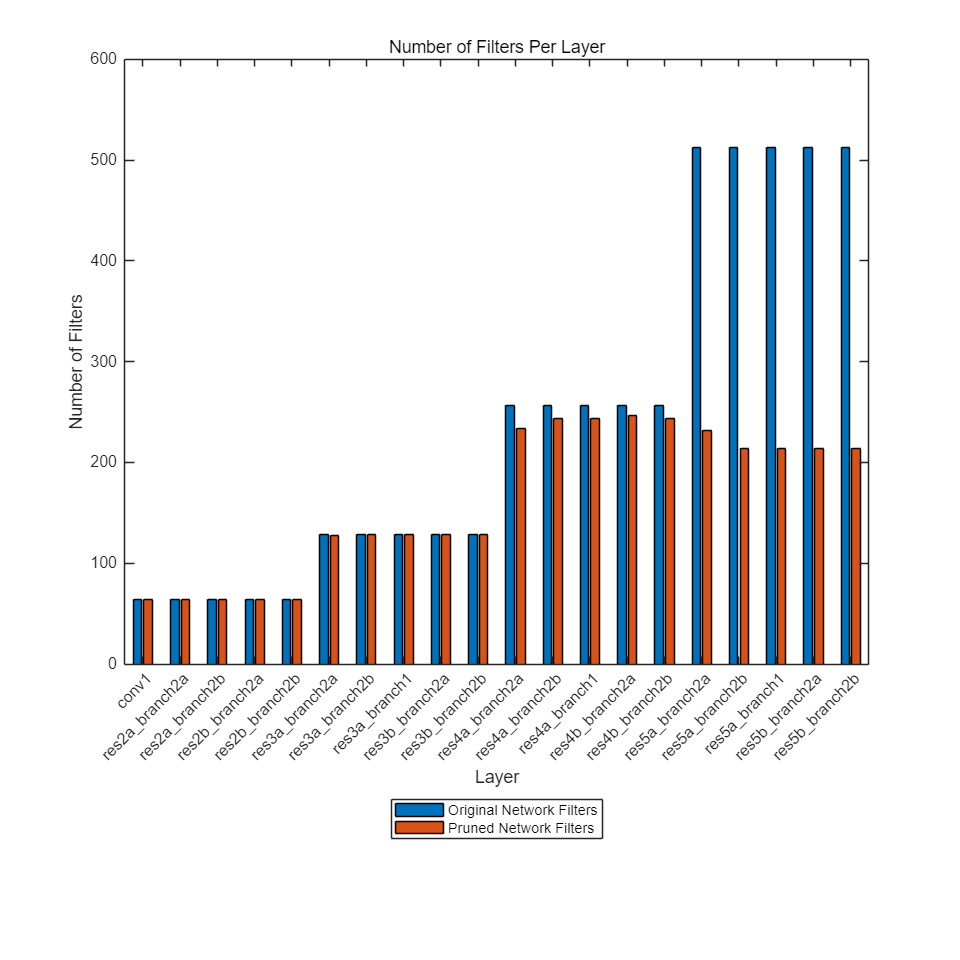

Pruning Iteration 4: Accuracy = 91.41%, Number of Prunable Filters = 2310


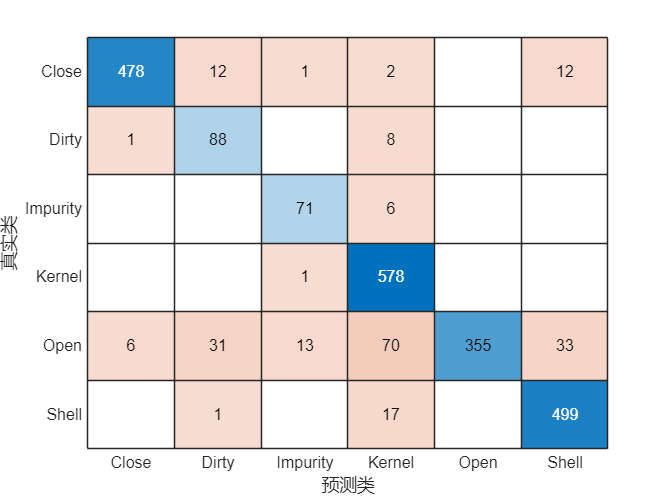

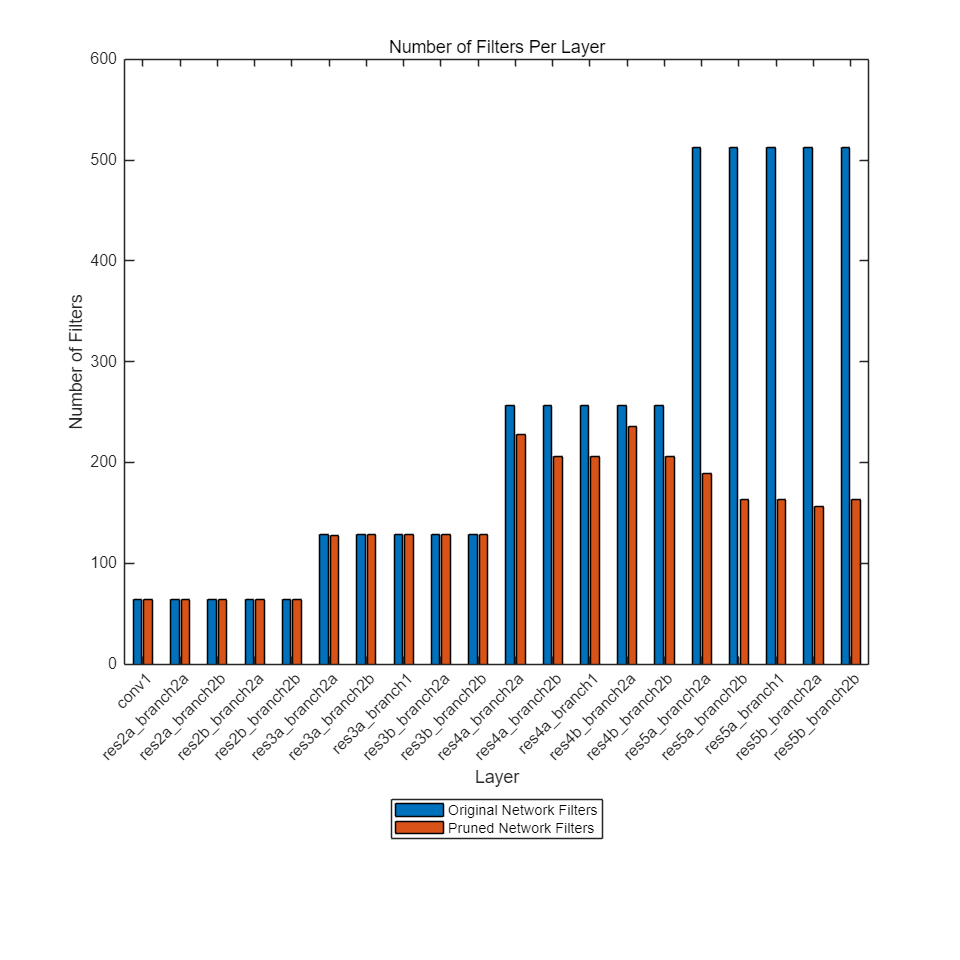

Pruning Iteration 5: Accuracy = 90.63%, Number of Prunable Filters = 1925


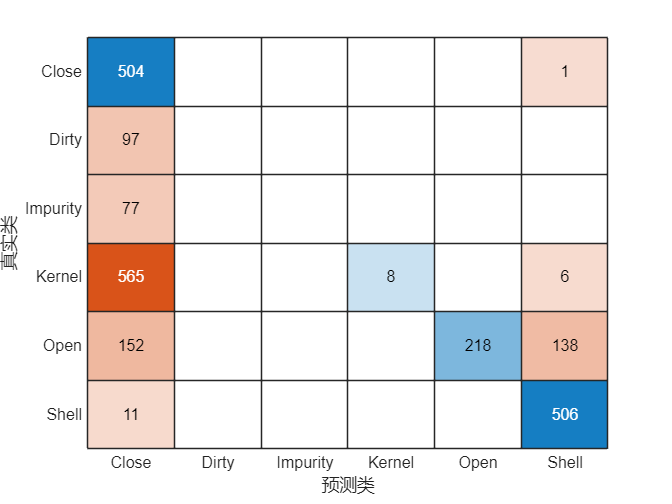

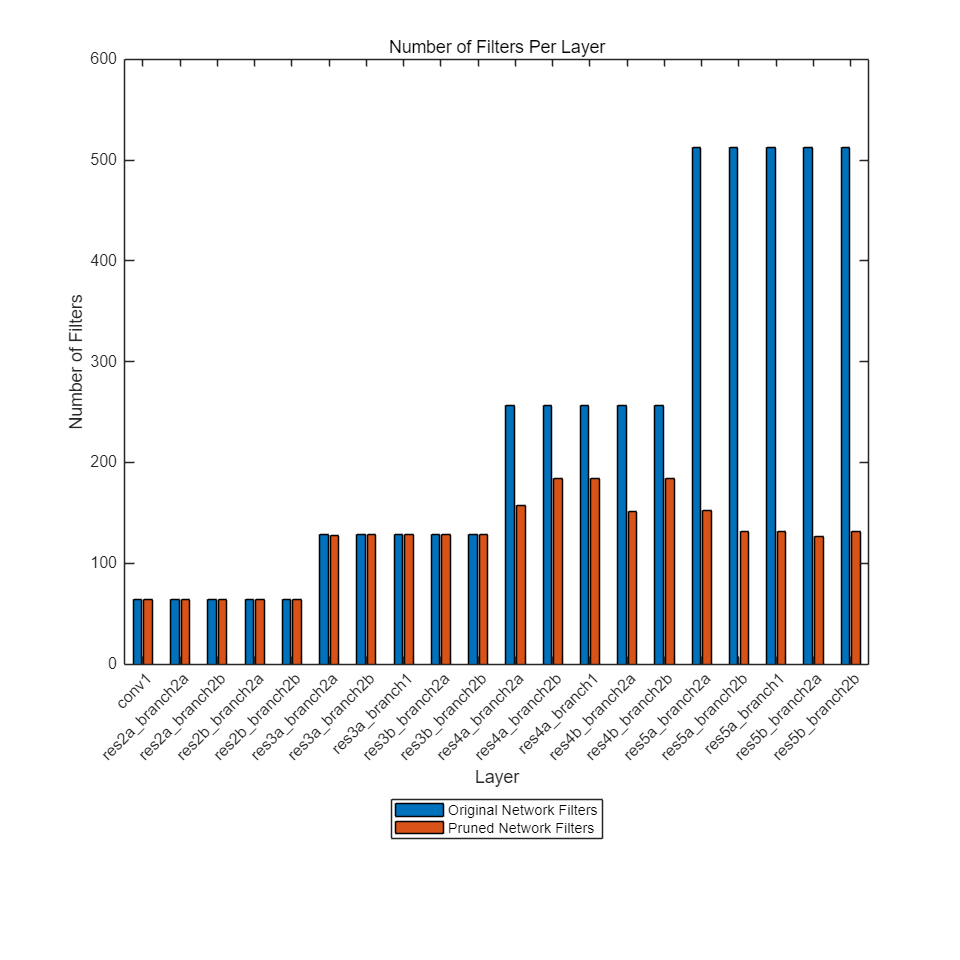

Pruning Iteration 6: Accuracy = 54.14%, Number of Prunable Filters = 1540


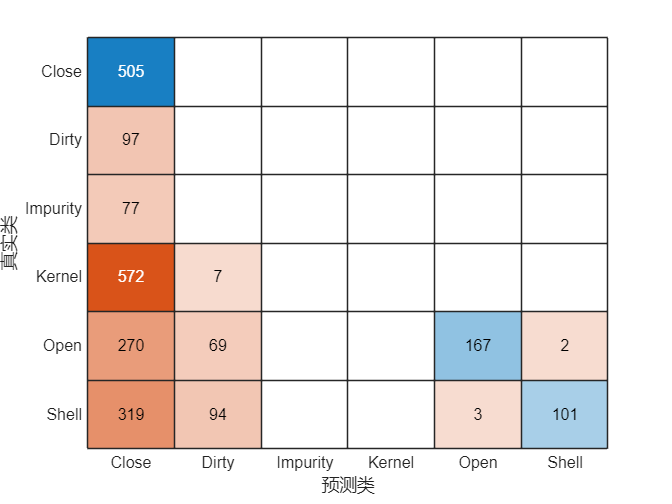

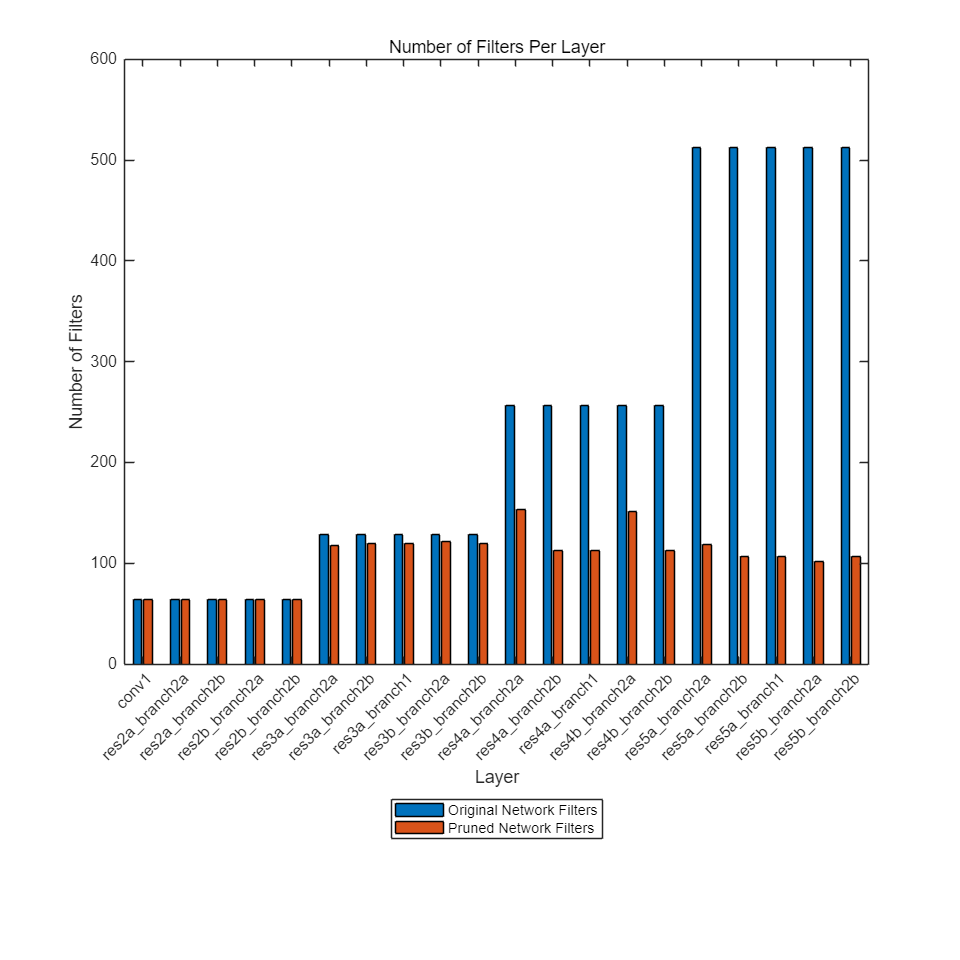

Pruning Iteration 7: Accuracy = 33.86%, Number of Prunable Filters = 1155


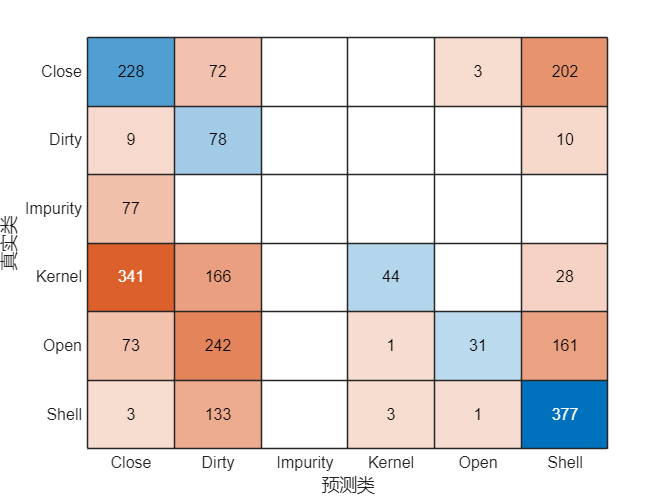

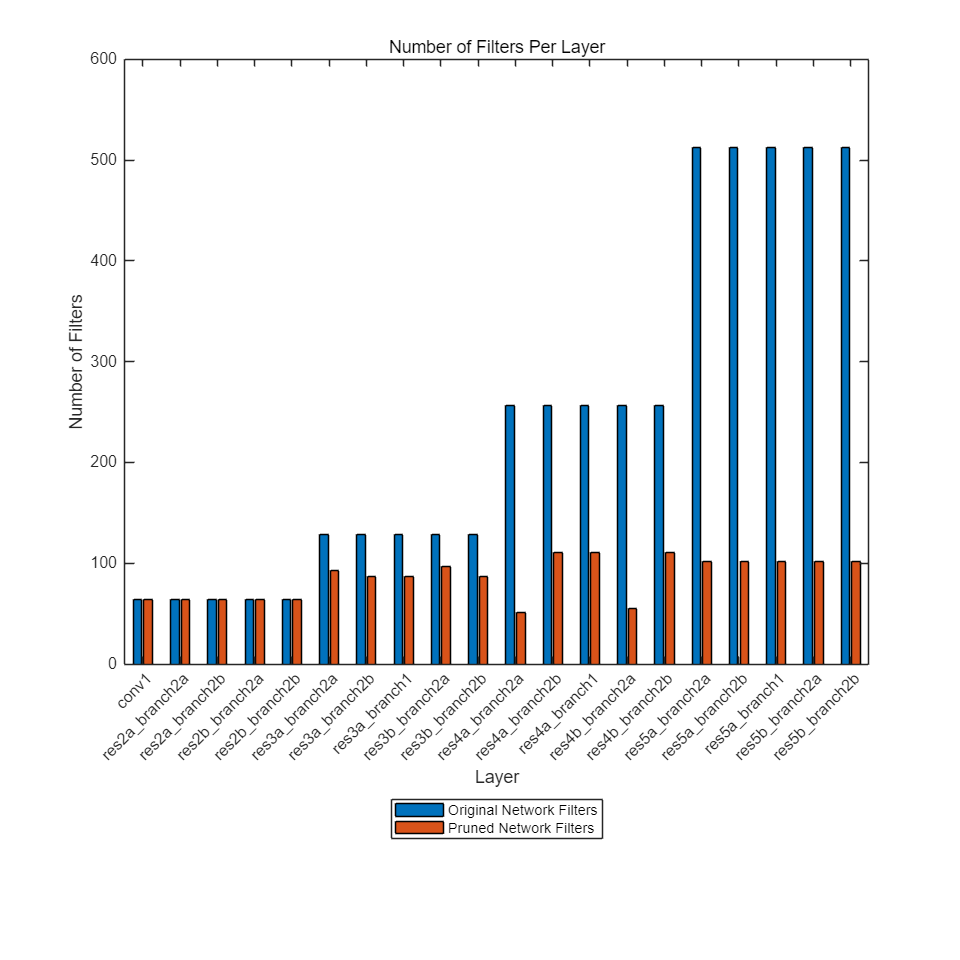

Pruning Iteration 8: Accuracy = 33.20%, Number of Prunable Filters = 770


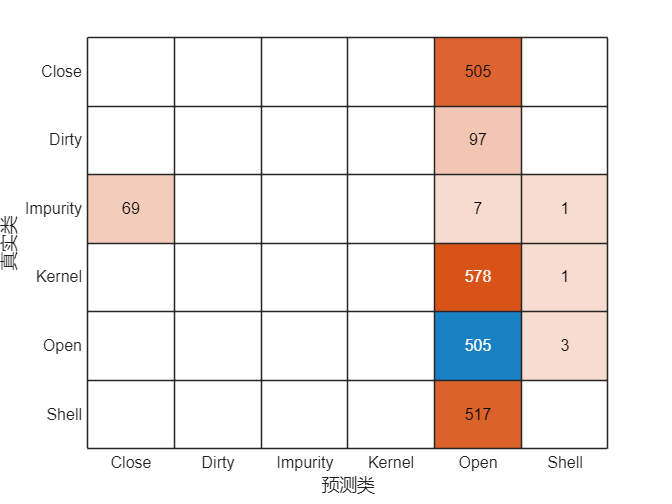

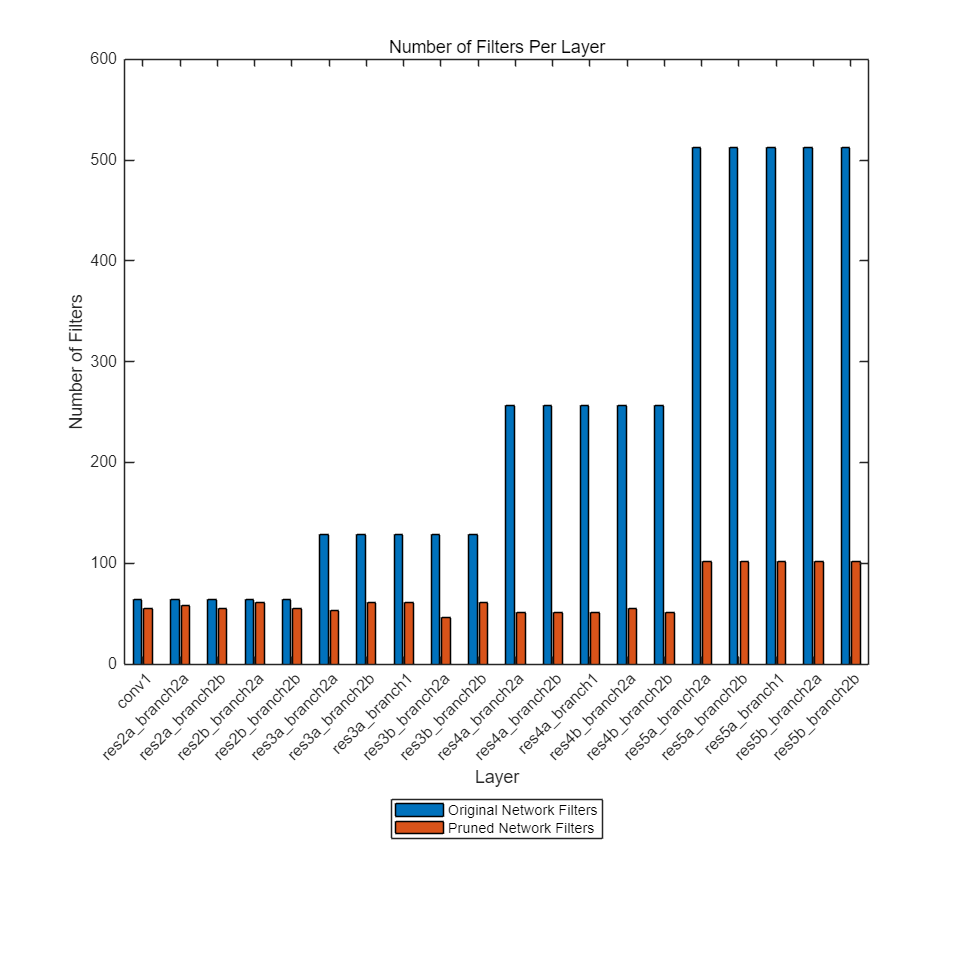

Pruning Iteration 9: Accuracy = 22.12%, Number of Prunable Filters = 385


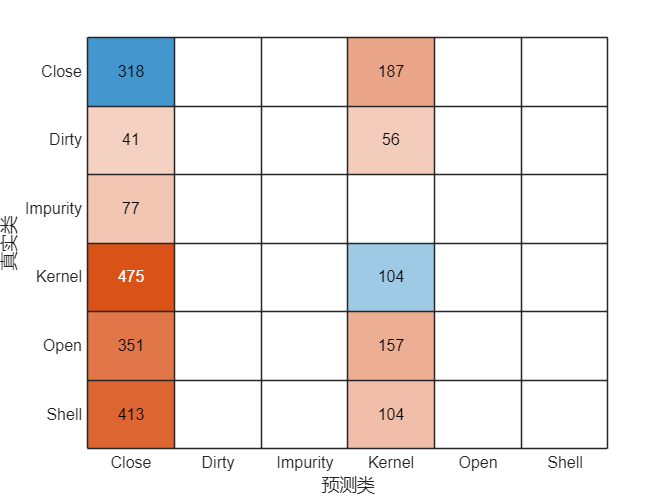

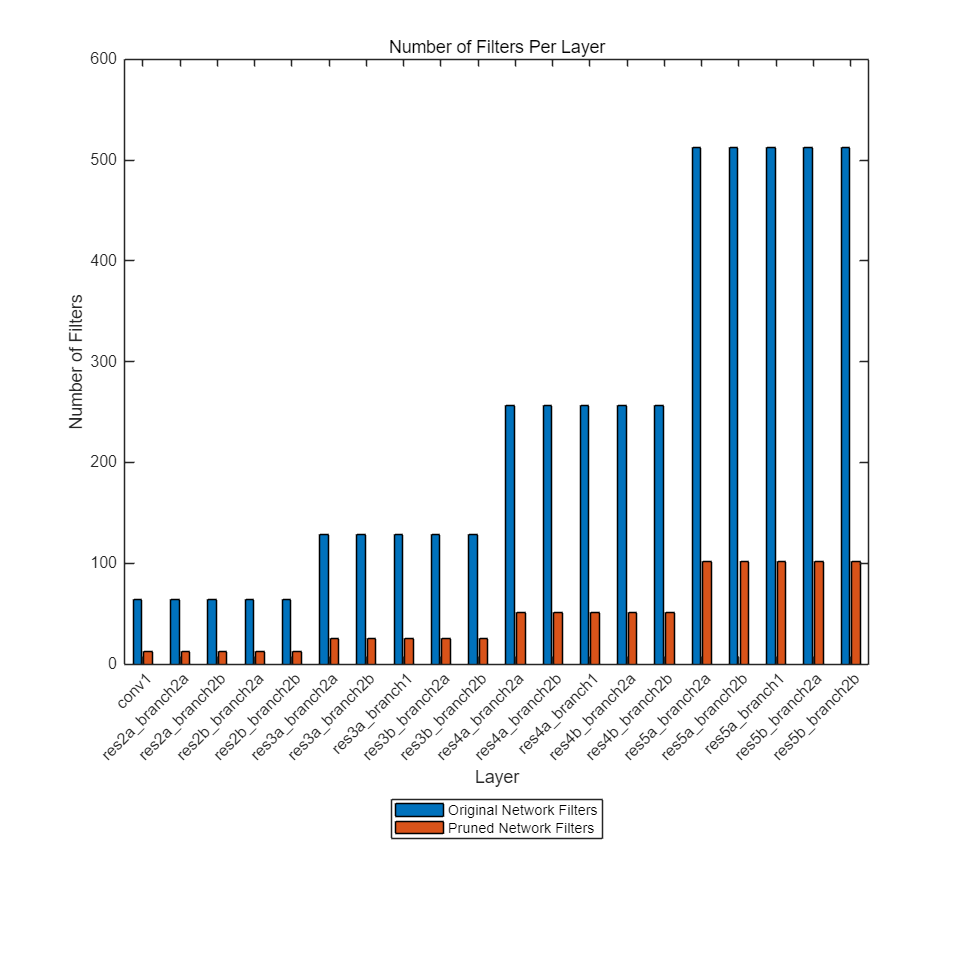

Pruning Iteration 10: Accuracy = 18.48%, Number of Prunable Filters = 0


% Record the start time and number of iterations
start = tic;
iteration = 0;
PPPP = zeros(10,20);
PPPACC = zeros(10,1);
% Start pruning iteration
for pruningIteration = 1:maxPruningIterations
    % Randomly rearrange the data
    shuffle(mbqTrain);

    % Reset the speed parameters of the SGDM optimizer.
    velocity = [];

    % Cycle through mini batches of data
    fineTuningIteration = 0;
    while hasdata(mbqTrain)
        iteration = iteration + 1;
        fineTuningIteration = fineTuningIteration + 1;

        % Read mini batch data
        [X, T] = next(mbqTrain);

        % Calculate loss, pruning activation, pruning gradient, network gradient, and state.
        [loss,pruningActivations, pruningGradients, netGradients, state] = ...
            dlfeval(@modelLossPruning, prunableNet, X, T);
        
        % Update network status
        prunableNet.State = state;
    
        % 使用 SGDM 优化器更新网络参数
        % [prunableNet, velocity] = sgdmupdate(prunableNet, netGradients, velocity, learnRate, momentum);

        % Calculate first-order Taylor scores and accumulate scores
        prunableNet = updateScore(prunableNet, pruningActivations, pruningGradients);

        % Show training progress
        D = duration(0,0,toc(start),Format="hh:mm:ss");
        addpoints(lineLossFinetune, iteration, double(loss))
        title(tl,"Processing Pruning Iteration: " + pruningIteration + " of " + maxPruningIterations + ...
            ", Elapsed Time: " + string(D))
        % Synchronize the x-axis of the accuracy and numPrunables plots with the loss plot.
        xlim(accuracyAx,lossAx.XLim)
        xlim(numPrunablesAx,lossAx.XLim)
        drawnow

        % Stop the fine-tuning loop when numMinibatchUpdates is reached.
        
        if (fineTuningIteration > numMinibatchUpdates)
            break
        end
    end

    % Calculated Taylor fraction pruning filter
    prunableNet = updatePrunables(prunableNet, MaxToPrune = maxToPrune);

    % Display the results on the validation dataset in some pruning iterations
    isLastPruningIteration = pruningIteration == maxPruningIterations;
    if (mod(pruningIteration, validationFrequency) == 0 || isLastPruningIteration)
        accuracy = modelAccuracy(prunableNet, mbqTest, classes, augimdsTest.NumObservations);
        addpoints(lineAccuracyPruning, iteration, accuracy)
        addpoints(lineNumPrunables,iteration,double(prunableNet.NumPrunables))
         
        % ADD
         prunableNet_process = dlnetwork(prunableNet); 
        YPredPruned_process = minibatchpredict(prunableNet_process,augimdsTest);
        YPredPruned_process = onehotdecode(YPredPruned_process,classNames,2);
        figure, confusionchart(TTest,YPredPruned_process);

        [originalNetFilters,layerNames] = numConvLayerFilters(trainedOriginalNet);
        prunedNetFilters = numConvLayerFilters(prunableNet_process);
        % Draw a bar chart of the number of filters
         PPPP(pruningIteration,:) = prunedNetFilters';
         PPPACC(pruningIteration,:) = accuracy;

        figure("Position",[10,10,900,900])

        bar([originalNetFilters,prunedNetFilters])
        xlabel("Layer")
        ylabel("Number of Filters")
        title("Number of Filters Per Layer")
        xticks(1:(numel(layerNames)))
        xticklabels(layerNames)
        xtickangle(45)
        ax = gca;
        ax.TickLabelInterpreter = "none";
        legend("Original Network Filters","Pruned Network Filters","Location","southoutside")


        % Outputs the accuracy and number of filters for the current iteration
        fprintf('Pruning Iteration %d: Accuracy = %.2f%%, Number of Prunable Filters = %d\n', ...%%%%%%%%%%%%%%%%%%%%%%
                pruningIteration, accuracy, prunableNet.NumPrunables); %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    end

    % 
    xTickPos = [xTickPos, iteration]; 
    xticks(lossAx,xTickPos)
    xticks(accuracyAx,[0,xTickPos])
    xticks(numPrunablesAx,[0,xTickPos])
    xticklabels(accuracyAx,["Unpruned",string(1:pruningIteration)])
    xticklabels(numPrunablesAx,["Unpruned",string(1:pruningIteration)])
    drawnow
end


% Network after pruning
prunedNet = dlnetwork(prunableNet); 
options = trainingOptions('adam', ...
'Plots','none',...         % 显示训练进度图
'Verbose',0,...                         % 不显示详细训练信息
'VerboseFrequency',50,...               % 每50个迭代显示一次训练信息
'MaxEpochs',10,...                      % 最大训练迭代次数为10
'MiniBatchSize',32,...                  % 每次迭代使用的批大小为500
'Shuffle','every-epoch',...             % 每次迭代随机打乱数据
'ValidationData',augimdsTest, ...       % 验证集数据
'ExecutionEnvironment','gpu');          % 使用自定义输出函数

% 使用剪枝后的网络进行微调   根据最大剪枝数量设置名称
prunedDAGNet130 = trainnet(augimdsTrain,prunedNet,"crossentropy",options); 
save('prunedDAGNet130','prunedDAGNet130');

% Calculate the number of filters in the original network and the pruned network
[originalNetFilters,layerNames] = numConvLayerFilters(trainedOriginalNet);
prunedNetFilters = numConvLayerFilters(prunedDAGNet130);
% Draw a bar chart of the number of filters
figure("Position",[10,10,900,900])
bar([originalNetFilters,prunedNetFilters])
xlabel("Layer")
ylabel("Number of Filters")
title("Number of Filters Per Layer")
xticks(1:(numel(layerNames)))
xticklabels(layerNames)
xtickangle(45)
ax = gca;
ax.TickLabelInterpreter = "none";
legend("Original Network Filters","Pruned Network Filters","Location","southoutside")

% Calculate the accuracy of the original network
YPredOriginal = minibatchpredict(trainedOriginalNet,augimdsTest);
YPredOriginal = onehotdecode(YPredOriginal,classNames,2);
accuOriginal = mean(YPredOriginal == TTest)

accuOriginal = 0.9855

% Calculate the accuracy of the network after pruning training
YPredPruned = minibatchpredict(prunedDAGNet130,augimdsTest);
YPredPruned = onehotdecode(YPredPruned,classNames,2);
accuPruned = mean(YPredPruned == TTest)

accuPruned = 0.9917

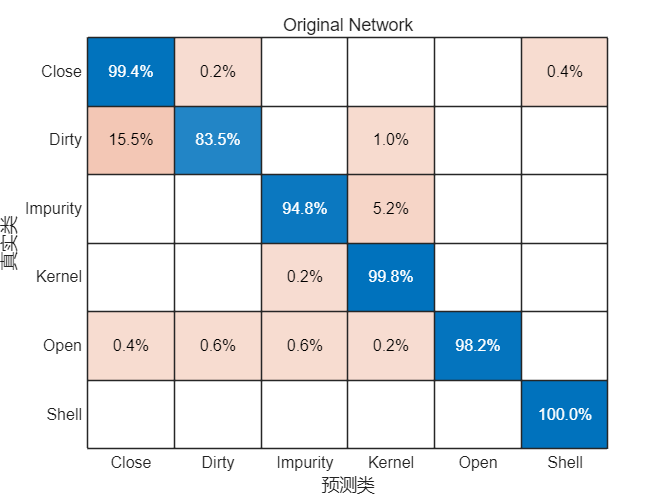

% Plot the confusion matrix of the original network
figure
confusionchart(TTest,YPredOriginal,Normalization = "row-normalized");
title("Original Network")

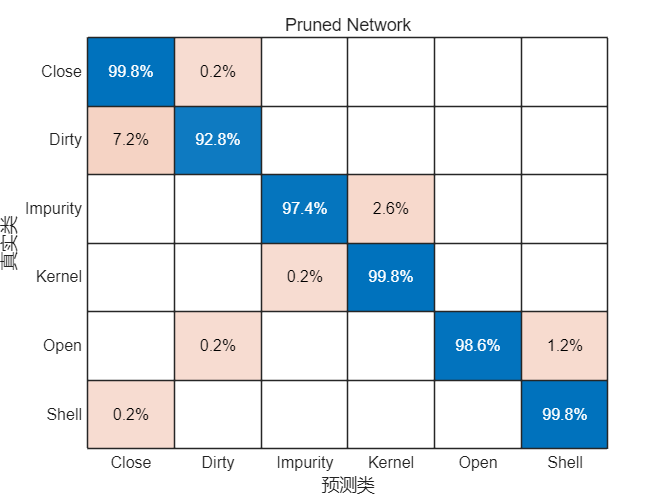

% Plot the confusion matrix of the network after pruning
figure
confusionchart(TTest,YPredPruned,Normalization = "row-normalized");
title("Pruned Network")

analyzeNetworkMetrics(trainedOriginalNet,prunedDAGNet130,accuOriginal,accuPruned) % 分析网络性能指标

ans = 3×3 table
                         Network Learnables    Approx. Network Memory (MB)    Accuracy
                         __________________    ___________________________    ________

    Original Network         1.1175e+07                   42.628              0.98555 
    Pruned Network            4.443e+05                   1.6949              0.99168 
    Percentage Change           -96.024                  -96.024              0.62222 


save prun_model_2view

function accuracy = modelAccuracy(net, mbq, classes, numObservations)
% This function computes the model accuracy of a net(dlnetwork) on the minibatchque 'mbq'.

totalCorrect = 0;

classes = int32(categorical(classes));

reset(mbq);

while hasdata(mbq)
    [dlX, Y] = next(mbq);

    dlYPred = extractdata(predict(net, dlX));

    YPred = onehotdecode(dlYPred,classes,1)';
    YReal = onehotdecode(Y,classes,1)';


    miniBatchCorrect = nnz(YPred == YReal);

    totalCorrect = totalCorrect + miniBatchCorrect;
end

accuracy = totalCorrect / numObservations * 100;
end

function [loss,pruningGradient,pruningActivations,netGradients,state] = modelLossPruning(prunableNet, X, T)

[dlYPred,state,pruningActivations] = forward(prunableNet,X);

loss = crossentropy(dlYPred,T);
[pruningGradient,netGradients] = dlgradient(loss,pruningActivations,prunableNet.Learnables);

end

function [X,T] = preprocessMiniBatchTraining(XCell,TCell)
% Concatenate.
X = cat(4,XCell{1:end});

% Extract label data from cell and concatenate.
T = cat(2,TCell{1:end});

% One-hot encode labels.
T = onehotencode(T,1);
end

function [nFilters, convNames] = numConvLayerFilters(net)
numLayers = numel(net.Layers);
convNames = [];
nFilters = [];
% Check for convolution layers and extract the number of filters.
for cnt = 1:numLayers
    if isa(net.Layers(cnt),"nnet.cnn.layer.Convolution2DLayer")
        sizeW = size(net.Layers(cnt).Weights);
        nFilters = [nFilters; sizeW(end)];
        convNames = [convNames; string(net.Layers(cnt).Name)];
    end
end
end

function [statistics] = analyzeNetworkMetrics(originalNet,prunedNet,accuracyOriginal,accuracyPruned)

originalNetMetrics = estimateNetworkMetrics(originalNet);
prunedNetMetrics = estimateNetworkMetrics(prunedNet);

% Accuracy of original network and pruned network
perChangeAccu = 100*(accuracyPruned - accuracyOriginal)/accuracyOriginal;
AccuracyForNetworks = [accuracyOriginal;accuracyPruned;perChangeAccu];

% Total learnables in both networks
originalNetLearnables = sum(originalNetMetrics(1:end,"NumberOfLearnables").NumberOfLearnables);
prunedNetLearnables = sum(prunedNetMetrics(1:end,"NumberOfLearnables").NumberOfLearnables);
percentageChangeLearnables = 100*(prunedNetLearnables - originalNetLearnables)/originalNetLearnables;
LearnablesForNetwork = [originalNetLearnables;prunedNetLearnables;percentageChangeLearnables];

% Approximate parameter memory
approxOriginalMemory = sum(originalNetMetrics(1:end,"ParameterMemory (MB)").("ParameterMemory (MB)"));
approxPrunedMemory = sum(prunedNetMetrics(1:end,"ParameterMemory (MB)").("ParameterMemory (MB)"));
percentageChangeMemory = 100*(approxPrunedMemory - approxOriginalMemory)/approxOriginalMemory;
NetworkMemory = [ approxOriginalMemory; approxPrunedMemory; percentageChangeMemory];

% Create the summary table
statistics = table(LearnablesForNetwork,NetworkMemory,AccuracyForNetworks, ...
    'VariableNames',["Network Learnables","Approx. Network Memory (MB)","Accuracy"], ...
    'RowNames',{'Original Network','Pruned Network','Percentage Change'});

end